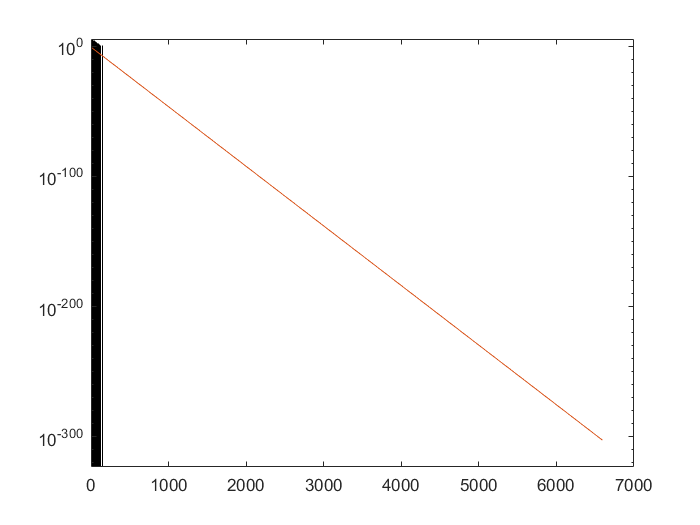

clear all; 

% Grid points along a dimension
t = 2*1:10^7; 

% Logical array along this dimension, that picks "1" at a constant
% probability
p = 0.1;
y = coinflip(t,p);

%figure;
%stem(t,y);
%ylim([0 2]);

% Find distance between coinflips that are heads
headsIndx = t(y>0);
distanceBetweenHeads = diff(headsIndx);

figure;
h=histogram(distanceBetweenHeads,'Normalization','countdensity');
set(gca,'YScale','log');
hold on;
plot(h.Values, exponential(h.Values, p));

% ylim([10^1 10^8]);

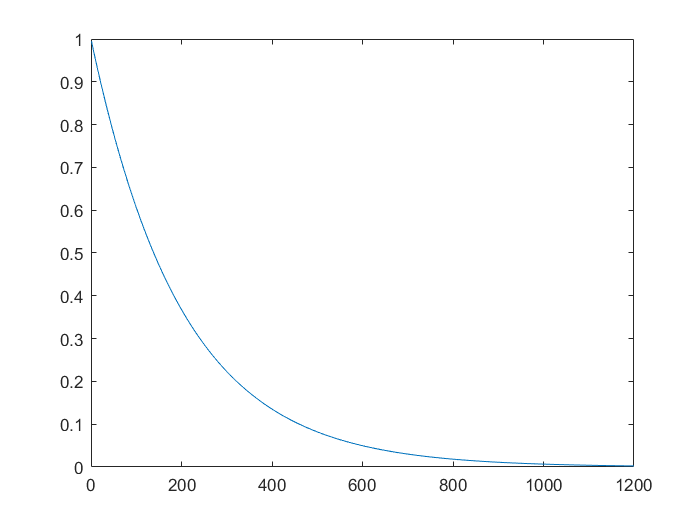

deltaT = 200;
lambda = 1/deltaT;
x = 1:1200;
figure;
plot(x,exp(-lambda*x));

function y=coinflip(t,p)
n = length(t);
y = zeros(n,1);
x = rand(n,1);
y(x<p) = 1;
end

function y = exponential(t,p)
y = p.*exp(log(1-p).*t);
end
